# Keyword Spotting Model with Streaming Audio from Microphnone Using MFCC and LSTM Network

After studying the MATLAB code from Keyword Spotting In Noise Using MFCC And LSTM Network, this code was constucted to understand how real-life evironment affect the accuracy of the nework on spottng kyord "Yes". LSTM network with different training obtained from the matlab code was interpreted here for answering the research question. 

## Research question

How can deep learning enhance wake word detection in noisy and real-world audio environments?

## Setup audio device reader

windowLength = 512;
overlapLength = 384;
hopLength = windowLength - overlapLength;
frameLength = hopLength;
adr = audioDeviceReader(SampleRate=fs,SamplesPerFrame=frameLength);

% Setup visualization scope 
scope = timescope(SampleRate=fs, ...
    TimeSpanSource="property", ...
    TimeSpan=5, ...
    TimeSpanOverrunAction="Scroll", ...
    BufferLength=fs*5*2, ...
    ShowLegend=true, ...
    ChannelNames={'Speech','Keyword Mask'}, ...
    YLimits=[-1.2,1.2], ...
    Title="Keyword Spotting");

% Define rate for mask estimation
numHopsPerUpdate = 16;

% Initialize audio buffer
dataBuff = dsp.AsyncBuffer(windowLength);

% Initilaize computed features buffer
featureBuff = dsp.AsyncBuffer(numHopsPerUpdate);

% Initialize plotting buffer 
plotBuff = dsp.AsyncBuffer(numHopsPerUpdate*windowLength);

Unrecognized function or variable 'KWSNet_Noise'.

## Audio recording and Keyword Detection

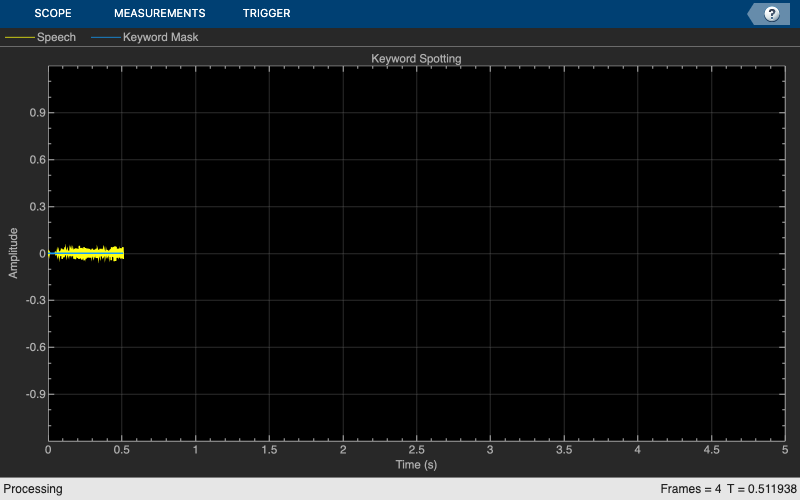

% Set the length of the audio recording
timeLimit = 10;
tic
while toc < timeLimit

    data = adr();
    write(dataBuff,data);
    write(plotBuff,data);

    frame = read(dataBuff,windowLength,overlapLength);
    features = generateKeywordFeatures(frame,fs);
    write(featureBuff,features.');

    if featureBuff.NumUnreadSamples == numHopsPerUpdate
        featureMatrix = read(featureBuff);
        featureMatrix(~isfinite(featureMatrix)) = 0;
        featureMatrix = (featureMatrix - M)./S;
        
        % Now the LSTM Network is used for detecting keywords
        [keywordNet,v] = classifyAndUpdateState(KWSNet,featureMatrix.');
        v = double(v) - 1;
        v = repmat(v,hopLength,1);
        v = v(:);
        v = mode(v);
        v = repmat(v,numHopsPerUpdate*hopLength,1);

        data = read(plotBuff);
        scope([data,v]);

        if ~isVisible(scope)
            break;
        end
    end
end

## Recorded Audio Testing

% Simple recording
[audioIn,fs] = audioread("keywordTestSignal.wav");
sound(audioIn,fs)

afe = audioFeatureExtractor(SampleRate=fs, ...
    Window=hann(windowLength,"periodic"),OverlapLength=overlapLength, ...
    mfcc=true,mfccDelta=true,mfccDeltaDelta=true);

features = extract(afe,audioIn);
features = (features - M)./S;

mask1 = classify(KWSNet,features.')

mask1 = 1×497 categorical array
     0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0   

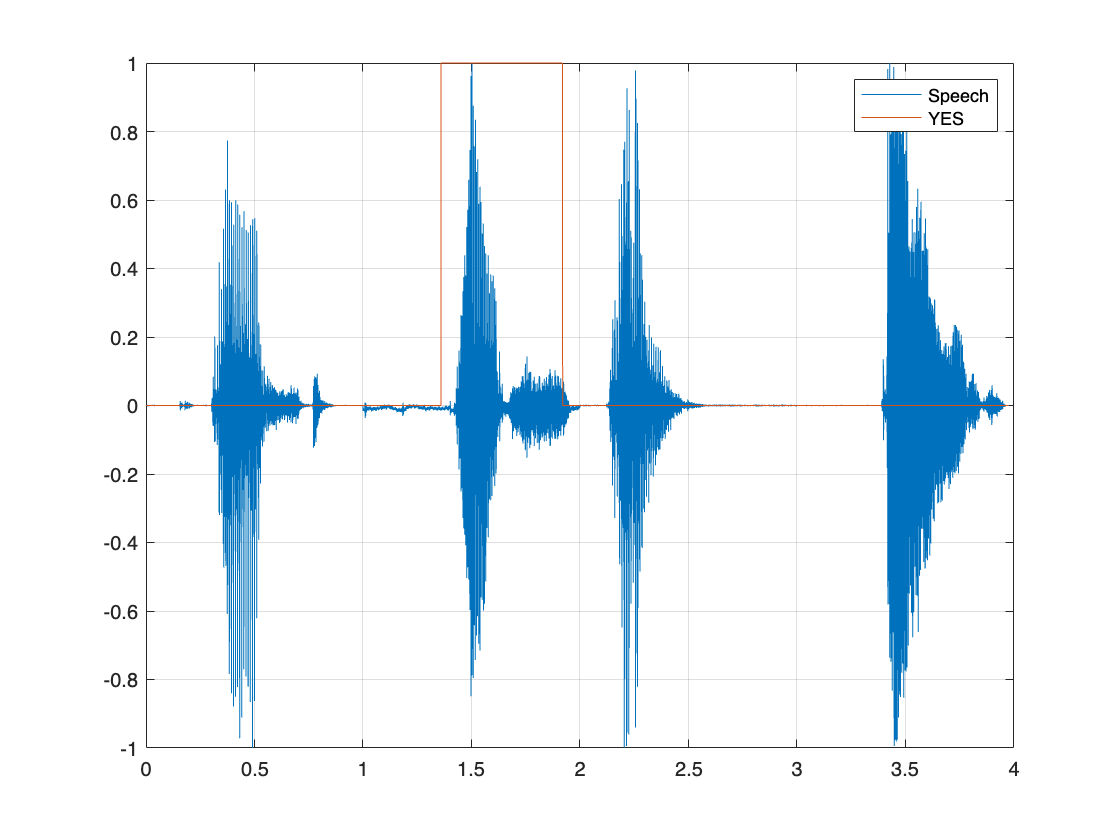

mask1 = repmat(mask1,windowLength-overlapLength,1);
mask1 = double(mask1) - 1;
mask1 = mask1(:);

sound(audioIn(mask1==1),fs)

figure
audioIn = audioIn(1:length(mask1));
t = (0:length(audioIn)-1)/fs;
plot(t,audioIn)
grid on
hold on
plot(t, mask1)
legend("Speech","YES")

## Longer Yes Audio with Different Speed


downloadFolder = matlab.internal.examples.downloadSupportFile("audio","KeywordSpotting.zip");
dataFolder = tempdir;
unzip(downloadFolder,dataFolder)
netFolder = fullfile(dataFolder,"KeywordSpotting");
load(fullfile(netFolder,"KWSNet.mat"));

[audioIn_speed,fs_speed] = audioread(fullfile(netFolder,"KeywordSpeech-16-16-mono-34secs.flac"));
sound(audioIn_speed,fs_speed)

features_speed = extract(afe,audioIn_speed);
features_speed = (features_speed - M)./S;

mask_speed = classify(KWSNet,features_speed.')

mask_speed = 1×4321 categorical array
  Columns 1 through 1428

     0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      

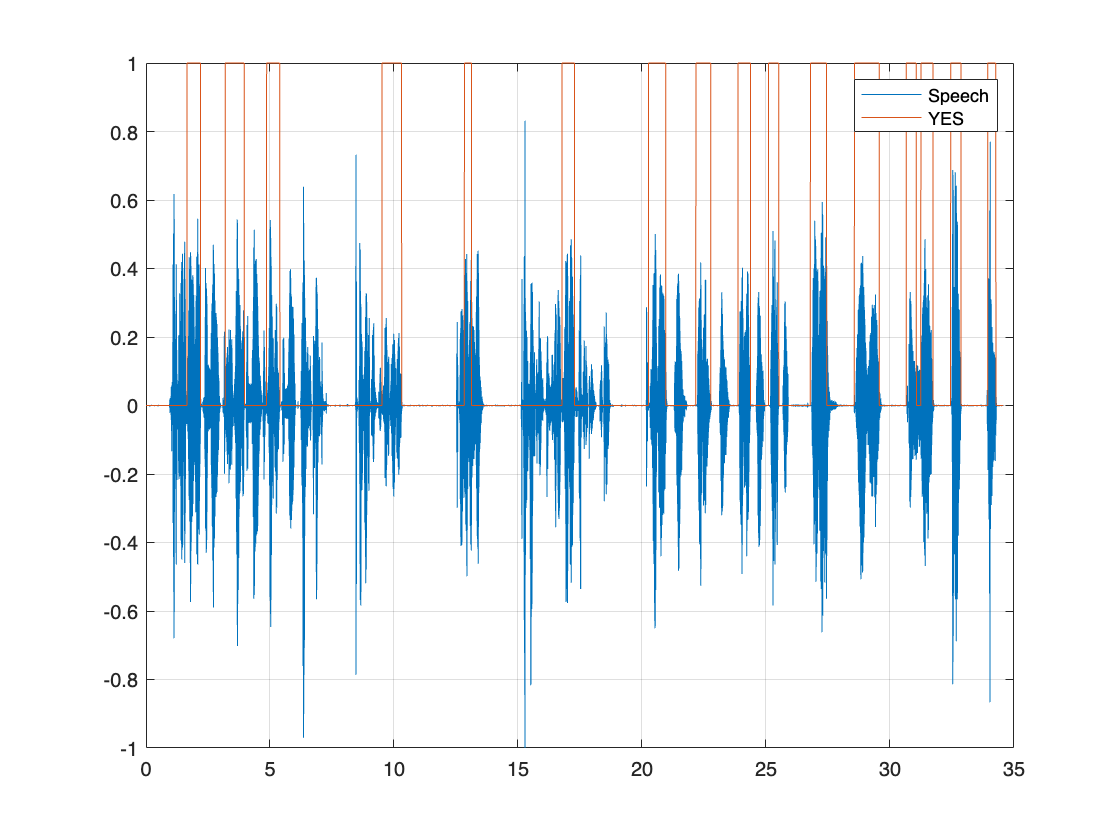

mask_speed = repmat(mask_speed,windowLength-overlapLength,1);
mask_speed = double(mask_speed) - 1;
mask_speed = mask_speed(:);

sound(audioIn_speed(mask_speed==1),fs_speed)

figure
audioIn_speed = audioIn_speed(1:length(mask_speed));
t = (0:length(audioIn_speed)-1)/fs_speed;
plot(t,audioIn_speed)
grid on
hold on
plot(t, mask_speed)
legend("Speech","YES")

## Background noise Inserted to Audio

[audioInNoisy,fsNoisy] = audioread(fullfile(netFolder,"NoisyKeywordSpeech-16-16-mono-34secs.flac"));
sound(audioInNoisy,fsNoisy)

featuresNoisy = extract(afe,audioInNoisy);
featuresNoisy = (featuresNoisy - M)./S;

maskNoisy = classify(KWSNet,featuresNoisy.')

maskNoisy = 1×4321 categorical array
  Columns 1 through 1428

     0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0

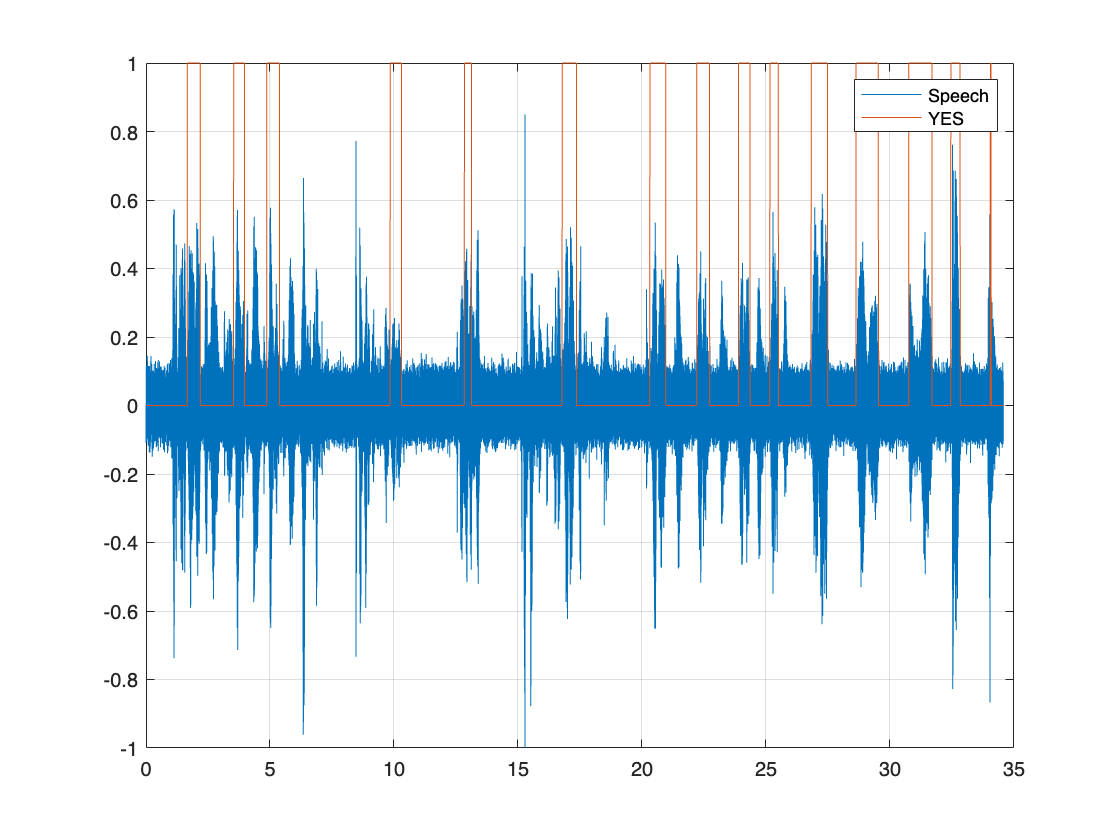

maskNoisy = repmat(maskNoisy,windowLength-overlapLength,1);
maskNoisy = double(maskNoisy) - 1;
maskNoisy = maskNoisy(:);

sound(audioInNoisy(maskNoisy==1),fs)

figure
audioInNoisy = audioInNoisy(1:length(maskNoisy));
t = (0:length(audioInNoisy)-1)/fs;
plot(t,audioInNoisy)
grid on
hold on
plot(t, maskNoisy)
legend("Speech","YES")

## Emotional Speech




% Different acsent and non native speaker (Further research)


## Testing with Different Feature Extractor Option

dataFolder = tempdir;
netFolder = fullfile(dataFolder,"KeywordSpotting");
[audioInNoisy,fsNoisy] = audioread(fullfile(netFolder,"NoisyKeywordSpeech-16-16-mono-34secs.flac"));

windowLength = 512;
overlapLength = 384;
hopLength = windowLength - overlapLength;
frameLength = hopLength;

% MFCC
afe1 = audioFeatureExtractor(SampleRate=fsNoisy, ...
    Window=hann(windowLength,"periodic"),OverlapLength=overlapLength, ...
    mfcc=true,mfccDelta=true,mfccDeltaDelta=true);

features1 = extract(afe1,audioInNoisy);
features1 = (features1 - M)./S;

mask1 = classify(KWSNet,features1.')

mask1 = 1×4321 categorical array
  Columns 1 through 1428

     0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0      0    


mask1 = repmat(mask1,windowLength-overlapLength,1);
mask1 = double(mask1) - 1;
mask1 = mask1(:);

% GTCC
afe2 = audioFeatureExtractor(SampleRate=fsNoisy, ...
    Window=hann(windowLength,"periodic"),OverlapLength=overlapLength, ...
    gtcc=true,gtccDelta=true,gtccDeltaDelta=true);

features2 = extract(afe2,audioInNoisy);
features2 = (features2 - M2)./S2;

mask2 = classify(KWSNet,features2.')

mask2 = 1×4321 categorical array
  Columns 1 through 1428

     1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1      1    

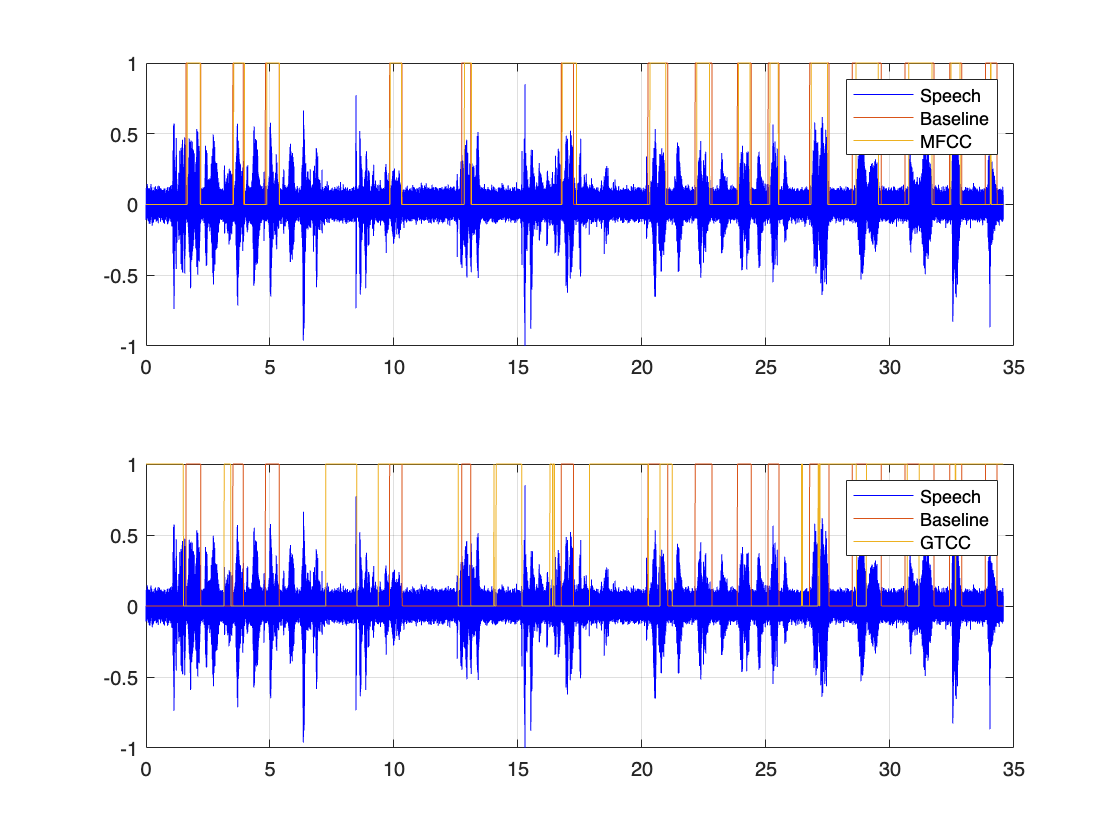


mask2 = repmat(mask2,windowLength-overlapLength,1);
mask2 = double(mask2) - 1;
mask2 = mask2(:);

% baseline 
baseline = double(BaselineV) - 1;
baseline = repmat(baseline,hopLength,1);
baseline = baseline(:);

% Plot
figure
audioInNoisy = audioInNoisy(1:length(mask2));
t = (0:length(audioInNoisy)-1)/fsNoisy;
tiledlayout(2,1)

nexttile
plot(t,audioInNoisy, color = 'b')
grid on
hold on
plot(t,baseline')
plot(t, mask1)
hold off
legend("Speech", "Baseline", "MFCC")

nexttile
plot(t,audioInNoisy, color = 'b')
grid on
hold on
plot(t,baseline')
plot(t, mask2)
hold off
legend("Speech", "Baseline", "GTCC")

% MFCC
sound(audioInNoisy(mask1==1),fsNoisy)

% GTCC
sound(audioInNoisy(mask2==1),fsNoisy)